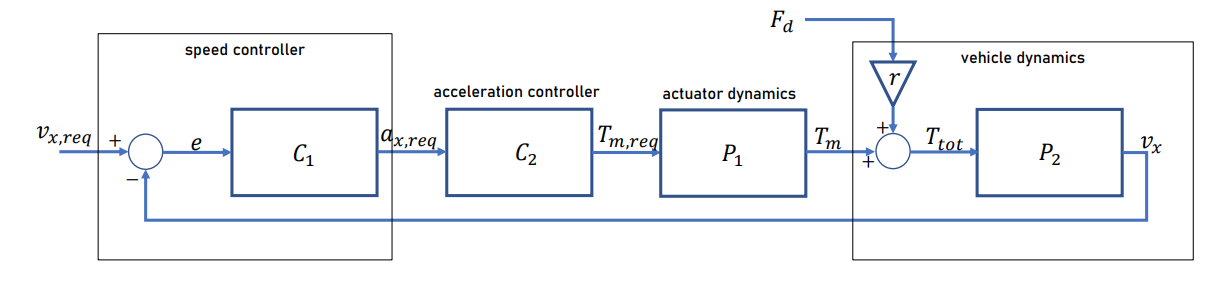

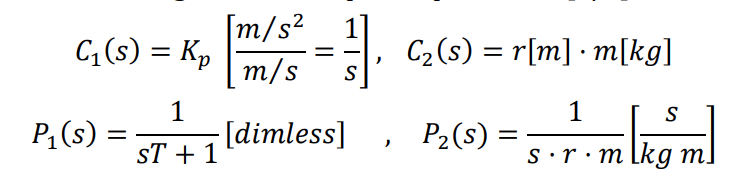

clc
clear
Kp = 2;
m = 2000;
r = 0.5;
T = 0.25;
g = 9.81;

C1 = tf(Kp);
C2 = tf(r*m);
P1 = tf(1,[T,1])

P1 =
 
      1
  ----------
  0.25 s + 1
 
Continuous-time transfer function.



P2 = tf(1,[r*m 0])

P2 =
 
    1
  ------
  1000 s
 
Continuous-time transfer function.



ol_sys = C1*C2*P1*P2

ol_sys =
 
        2000
  ----------------
  250 s^2 + 1000 s
 
Continuous-time transfer function.



cl_sys = feedback(ol_sys,1)

cl_sys =
 
           2000
  -----------------------
  250 s^2 + 1000 s + 2000
 
Continuous-time transfer function.



pole(cl_sys)

ans =   -2.0000 + 2.0000i
  -2.0000 - 2.0000i


cl_sys = tf(Kp,[T 1 Kp])

cl_sys =
 
         2
  ----------------
  0.25 s^2 + s + 2
 
Continuous-time transfer function.



pole(cl_sys)

ans =   -2.0000 + 2.0000i
  -2.0000 - 2.0000i


stable

Task c)

Fd = -m*g*sin(atan(0.1));
cl_sys2 = r*P2/(1+C1*C2*P1*P2)

cl_sys2 =
 
         125 s^2 + 500 s
  ------------------------------
  250000 s^3 + 1e06 s^2 + 2e06 s
 
Continuous-time transfer function.



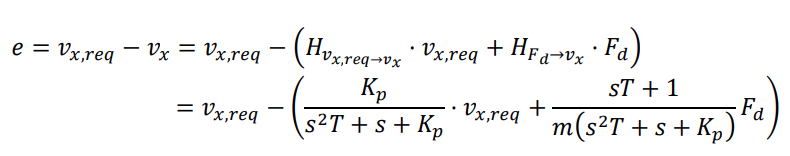

steady state, s=0

e = -1/(m*Kp)*Fd

e = 0.4881

Kp grows, e drops